# **Robot Model**

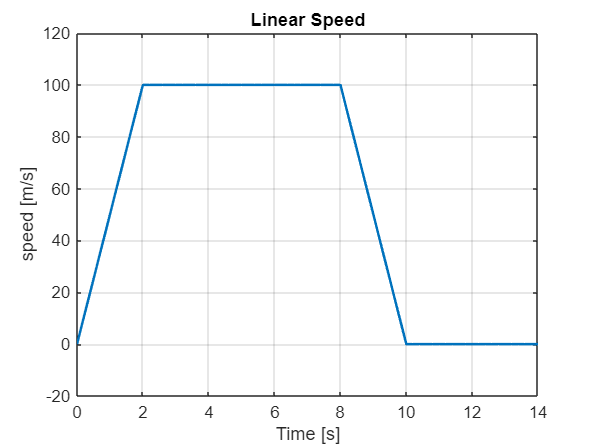

clear;
clc;
Ts = 0.2;
% Distance to Point P
l = 1;

% Delta Time
delta_t = Ts;
% Time
t = 0:delta_t:10+20*Ts;

% Trapezoidal Speed
speed_max = 100;
v = speed_max/2*ramp(t) - speed_max/2*ramp(t-2) - speed_max/2*ramp(t-8) + speed_max/2*ramp(t-10);

% Speed Plot
figure;
plot(t, v, 'LineWidth', 1.5);
grid on;
xlabel('Time [s]');
ylabel('speed [m/s]');
title('Linear Speed');

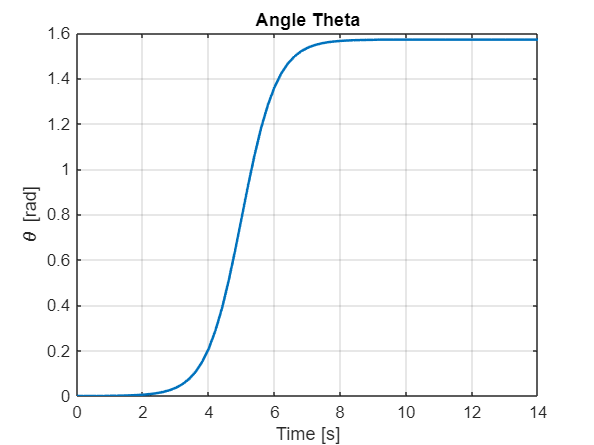

% Parameters
theta_0 = 0;          % [rad]
theta_f = pi/2;         % [rad]
t_start_turn = 1;          % Turn start [s]
t_end_turn = 9;             % Turn end [s]
k = 15;                     % sigmoid slope

% Angle
theta_ref = zeros(size(t));

for i = 1:length(t)
    if t(i) < t_start_turn
        % Before starting the turn, we keep the same heading
        theta_ref(i) = theta_0;
    elseif t(i) > t_end_turn
        % After the end of the turn, we keep the same heading
        theta_ref(i) = theta_f;
    else
        % in the turn we use a sigmoid
        tau = (t(i) - t_start_turn) / (t_end_turn - t_start_turn);  % time normalization
        theta_ref(i) = theta_0 + (theta_f - theta_0) / (1 + exp(-k * (tau - 0.5)));
    end
end

% Plot of the heading angle
figure;
plot(t, theta_ref, 'LineWidth', 1.5);
grid on;
xlabel('Time [s]');
ylabel('\theta [rad]');
title('Angle Theta');

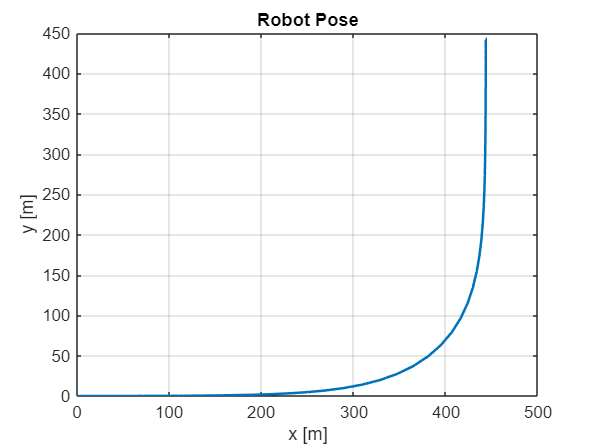

% Initial Position
x0 = 0;
y0 = 0;

% Trajectory of the Robot
pose = zeros(2, length(t));
pose(:,1) = [x0 y0]';

for i = 2:length(t)
    % Update x
    pose(1, i) = pose(1, i-1) + v(i)*cos(theta_ref(i))*delta_t;
    % Upate y
    pose(2, i) = pose(2, i-1) + v(i)*sin(theta_ref(i))*delta_t;
end

figure()
plot(pose(1,:), pose(2,:), 'LineWidth', 1.5);
grid on;
xlabel('x [m]');
ylabel('y [m]');
title('Robot Pose');

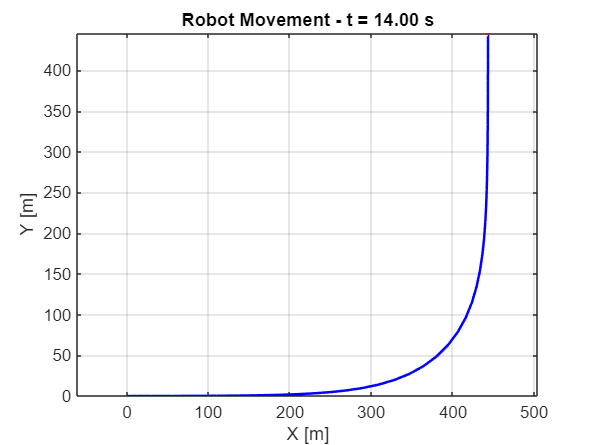

figure;
for i = 1:length(t)
    plot(pose(1,1:i), pose(2,1:i), 'b', 'LineWidth', 1.5); hold on; % Path traversed
    quiver(pose(1,i), pose(2,i), cos(theta_ref(i)), sin(theta_ref(i)), 2.5, 'r', 'LineWidth', 1.5);
    axis equal;
    grid on;
    xlabel('X [m]');
    ylabel('Y [m]');
    %xlim([0,50]);
    %ylim([0,45])
    title(sprintf('Robot Movement - t = %.2f s', t(i)));
    drawnow;
    hold off;
end

## MPC Test

% Control Signal
n = 2;
n_u = 2;

% Control Horizon
N = 10;

N_tot = 3*length(t);
u = zeros(n_u, N_tot - N);
x_history = zeros(n, N_tot - N +1);

% Control Matrices
Q = 10*eye(2);
R = 2*eye(2);
P = 12*eye(2);
Y = 3*eye(2);

% Radius of the attraction ball
epsilon = 0.3;

% Robot Parameters
d = 0.5;    % Distance between Wheels [m]
r = 0.25;   % Wheel Radius [m]
robot_params = [d, l, r];

## Simulation Parking

% Initial Pose
xk = [x0 y0]';
x_history(:,1) = xk;

k = 1;

for i = 1:length(u)
    k

    current_ref_start = pose(:, k)

    % We calculate the distance between the actual position and the
    % current_ref_start
    xk
    distance_to_ref = norm(xk-current_ref_start)

    % We update the current_ref_start
    if distance_to_ref < epsilon && k < (size(pose,2)-N)
        % updating if we are inside a ball of radius epsilon
        k = k +1;
    end

    % First we take the useful parameters of the trajectory
    poseRef = pose(:, k:k+N);
    thetaRef = theta_ref(1, k:k+N);
    % Computing the control signals
    u(:,i) = FHOCP(xk, Q, R, P, Y, N, n, n_u, delta_t, poseRef, thetaRef, robot_params);
    % Updating the State
    [xk, yk] = model_Robot_pointP(xk, u(:,i), delta_t);
    % States
    x_history(:,i+1) = xk;
end


% Initial Pose
xk = [x0 y0]';
x_history(:,1) = xk;

k = 1;

for i = 1:length(u)
    k

    current_ref_start = pose(:, k)

    % We calculate the distance between the actual position and the
    % current_ref_start
    xk
    distance_to_ref = norm(xk-current_ref_start)

    % We update the current_ref_start
    if distance_to_ref < epsilon && k < (size(pose,2)-N)
        % updating if we are inside a ball of radius epsilon
        k = k +1;
    end

    % First we take the useful parameters of the trajectory
    poseRef = pose(:, k:k+N);
    thetaRef = theta_ref(1, k:k+N);
    % Computing the control signals
    u(:,i) = FHOCP(xk, Q, R, P, Y, N, n, n_u, delta_t, poseRef, thetaRef, robot_params);
    % Updating the State
    [xk, yk] = model_Robot_pointP(xk, u(:,i), delta_t);
    % States
    x_history(:,i+1) = xk;
end

k = 1

current_ref_start =      0
     0


xk =      0
     0


distance_to_ref = 0


******************************************************************************
This program contains Ipopt, a library for large-scale nonlinear optimization.
 Ipopt is released as open source code under the Eclipse Public License (EPL).
         For more information visit https://github.com/coin-or/Ipopt
******************************************************************************

Restrictions were met.


k = 2

current_ref_start =      2
     0


xk =     4.5000
    0.0000


distance_to_ref = 2.5000

Restrictions were met.


k = 2

current_ref_start =      2
     0


xk =     9.0000
    0.0000


distance_to_ref = 7.0000

Restrictions were met.


k = 2

current_ref_start =      2
     0


xk =    13.5000
    0.0000


distance_to_ref = 11.5000

Restrictions were met.


k = 2

current_ref_start =      2
     0


xk =    18.0000
    0.0000


distance_to_ref = 16.0000

Restrictions were met.


k = 2

current_ref_start =      2
     0


xk =    22.5000
    0.0000


distance_to_ref = 20.5000

Restrictions were met.


k = 2

current_ref_start =      2
     0


xk =    27.0000
    0.0000


distance_to_ref = 25.0000

Restrictions were met.


k = 2

current_ref_start =      2
     0


xk =    31.5000
    0.0000


distance_to_ref = 29.5000

Restrictions were met.


k = 2

current_ref_start =      2
     0


xk =    36.0000
    0.0000


distance_to_ref = 34.0000

Restrictions were met.


k = 2

current_ref_start =      2
     0


xk =    38.0805
    0.0000


distance_to_ref = 36.0805

Restrictions were met.


k = 2

current_ref_start =      2
     0


xk =    38.7516
    0.0000


distance_to_ref = 36.7516

Restrictions were met.


k = 2

current_ref_start =      2
     0


xk =    38.9681
    0.0000


distance_to_ref = 36.9681

Restrictions were met.


k = 2

current_ref_start =      2
     0


xk =    39.0379
    0.0000


distance_to_ref = 37.0379

Restrictions were met.


k = 2

current_ref_start =      2
     0


xk =    39.0605
    0.0000


distance_to_ref = 37.0605

Restrictions were met.


k = 2

current_ref_start =      2
     0


xk =    39.0677
    0.0000


distance_to_ref = 37.0677

Restrictions were met.


k = 2

current_ref_start =      2
     0


xk =    39.0701
    0.0000


distance_to_ref = 37.0701

Restrictions were met.


k = 2

current_ref_start =      2
     0


xk =    39.0708
    0.0000


distance_to_ref = 37.0708

Restrictions were met.


k = 2

current_ref_start =      2
     0


xk =    39.0711
    0.0000


distance_to_ref = 37.0711

Restrictions were met.


k = 2

current_ref_start =      2
     0


xk =    39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start =      2
     0


xk =    39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start =      2
     0


xk =    39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start =      2
     0


xk =    39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start =      2
     0


xk =    39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start =      2
     0


xk =    39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start =      2
     0


xk =    39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


k = 2

current_ref_start = 2×1
     2
     0


xk = 2×1
   39.0712
    0.0000


distance_to_ref = 37.0712

Restrictions were met.


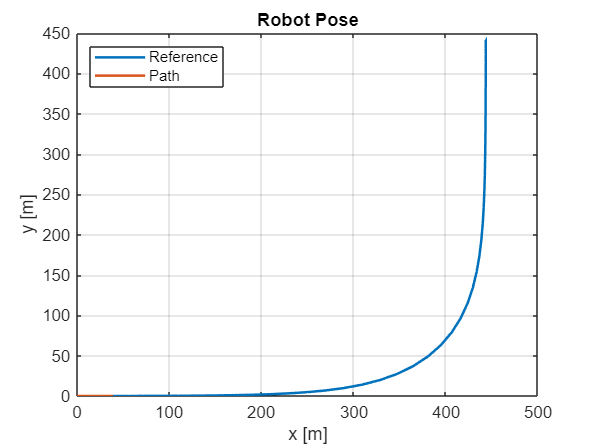

figure()
plot(pose(1,:), pose(2,:), 'LineWidth', 1.5);
hold on;
plot(x_history(1,:), x_history(2,:), 'LineWidth', 1.5);
grid on;
xlabel('x [m]');
ylabel('y [m]');
title('Robot Pose');
legend('Reference', 'Path', Location='northwest')

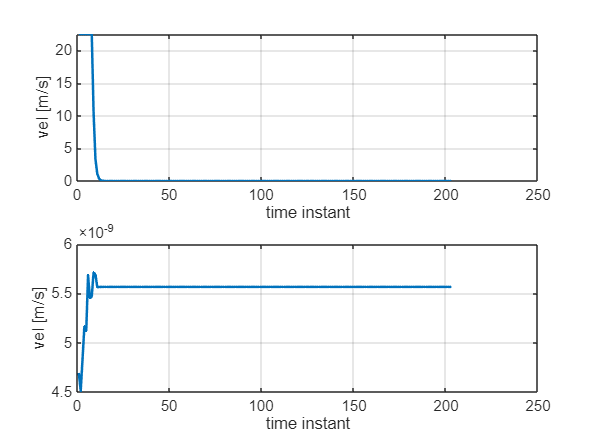



vel_x = u(1,:);
vel_y = u(2,:);
w_wheels = zeros(2, length(vel_y));
theta_sim = atan2(x_history(2,:),x_history(1,:));
for i = 1:length(vel_y)
    M = transformationMatrix(theta_sim(i), robot_params);
    w_wheels(:,i) = M*[vel_x(i); vel_y(i)];
end

w_r = w_wheels(1,:);
w_l = w_wheels(2, :);

figure()
subplot(2,1,1)
plot(vel_x, 'LineWidth', 1.5);
grid on;
xlabel('time instant');
ylabel('vel [m/s]');
subplot(2,1,2)
plot(vel_y, 'LineWidth', 1.5);
grid on;
xlabel('time instant');
ylabel('vel [m/s]');

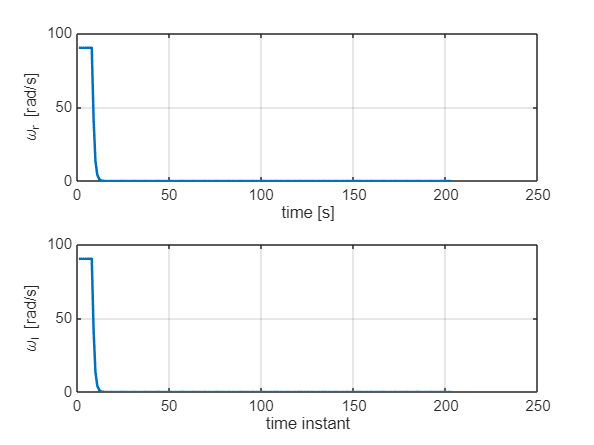




figure()
subplot(2,1,1)
plot(w_r, 'LineWidth', 1.5);
grid on;
xlabel('time [s]');
ylabel('\omega_r [rad/s]');
subplot(2,1,2)
plot(w_l, 'LineWidth', 1.5);
grid on;
xlabel('time instant');
ylabel('\omega_l [rad/s]');

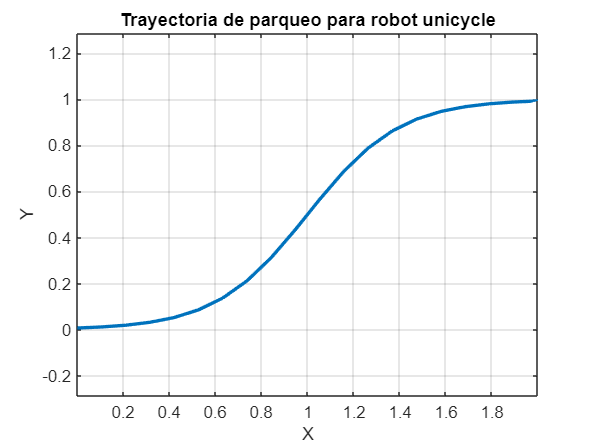

% Parámetro de la trayectoria
t = linspace(0, 1, 20);

% Punto inicial y final
x0 = 0;   y0 = 0;
xf = 2;   yf = 1;

% Trayectoria suave tipo sigmoide
X_ref = x0 + (xf - x0) * t;
Y_ref = y0 + (yf - y0) * (1 ./ (1 + exp(-10*(t - 0.5))));

X_ref = [X_ref X_ref(end)*ones(1,10)];
Y_ref = [Y_ref Y_ref(end)*ones(1,10)];

pose = [X_ref;Y_ref];

% Graficar
figure()
plot(X_ref, Y_ref, 'LineWidth', 2); grid on; axis equal;
xlabel('X'); ylabel('Y');
title('Trayectoria de parqueo para robot unicycle');

%pose_time = [t', pose'];
%theta_time = [t', theta_ref'];


pose = [5; 5];
theta_ref = pi;

function x = ramp(t)
    x = t.*(t>=0);
end